%%%%%%%%%%%%define continue state space%%%%%%%%%%%%%%
syms a b c p q r; 
A=[0 1 0 0;b 0 0 a;0 0 0 1;q 0 0 p];
B=[0;c;0;r];

%%%%%%%%%%%Discretization of a state-space model%%%%%%%%%
%y=theta_1
C=[1 0 0 0];
%a=-0.9421,b=82.7231,c=14.2306,p=-3.7808,q=4.9952,r=57.1120;
A=double(subs(A,{a,b,c,p,q,r},{-0.9421,82.7231,14.2306,-3.7808,4.9952,57.1120}));
B=double(subs(B,{a,b,c,p,q,r},{-0.9421,82.7231,14.2306,-3.7808,4.9952,57.1120}));
D=0;
h=0.1;
%%%%%%continue system%%%%%%%%%%%%%%%%%
sys=ss(A,B,C,D);
%%%%%%discrete system%%%%%%%%%%%%%%%%%
sys_d=c2d(sys,h);
A_d=sys_d.a

A_d =     1.4421    0.1143         0   -0.0045
    9.4370    1.4421         0   -0.0908
    0.0237    0.0008    1.0000    0.0833
    0.4814    0.0237         0    0.6845


B_d=sys_d.b

B_d =     0.0677
    1.3715
    0.2530
    4.7660


C_d=sys_d.c

C_d =      1     0     0     0


%%%%%%delay of the system%%%%%%%%%%%%%
t=0.8*h;
M=expm([A,B;0 0 0 0 0]*t);
At=M(1:4,1:4);
Bt=M(1:4,5);
M2=expm([A,B;0 0 0 0 0]*0.2*t);
A_ht=M2(1:4,1:4);
B_ht=M2(1:4,5);
A11=A_ht*At;
B11=A_ht*Bt;
B22=B_ht;
A_delay=[A11,B11;0 0 0 0 0]

A_delay =     1.4053    0.1087         0   -0.0041    0.0605
    8.9677    1.4053         0   -0.0868    1.0890
    0.0219    0.0007    1.0000    0.0805    0.2271
    0.4601    0.0219         0    0.6950    3.7203
         0         0         0         0         0


B_delay=[B22;1]

B_delay =     0.0018
    0.2217
    0.0072
    0.8867
    1.0000


C_delay=[1 0 0 0 0];
eigvalue_A_d=eig(A_d)

eigvalue_A_d =     1.0000
    2.4781
    0.4008
    0.6899


eigenvalue_A_delay=eig(A_delay)

eigenvalue_A_delay =     1.0000
    2.3898
    0.4157
    0.7002
         0


clc


%%%%%%%characters of LQ problem%%%%%%%%%%%%%%%%%%
A2=[1.0041 0.0100 0 0;0.8281 1.0041 0 -0.0093;0.0002 0.0000 1 0.0098;0.0491 0.0002 0 0.9629];
B2=[0.0007 0.1398 0.0028 0.5605]';
C2=[1 0 0 0;0 0 1 0];
Q=eye(4);
R=1;
Pf=10*eye(4);
N_input=1000;

%%%%%%%calculate with dp%%%%%%%%%%%%%%%%%%%%%%
[K_dp,P0,eigvalue_dp,N] =dp_func(A2,B2,N_input,Q,R,Pf)

This is the result of dp solution
the stable value of dp is 33

K_dp =   -46.1566   -5.2278    0.0155    0.4031


P0 = 1.0e+04 *

    3.0780    0.3401   -0.0201   -0.0731
    0.3401    0.0382   -0.0023   -0.0082
   -0.0201   -0.0023    0.0042    0.0006
   -0.0731   -0.0082    0.0006    0.0020


eigvalue_dp =     0.5584
    0.9236
    0.9524
    0.9996


N = 33

%%%%%%%%%%solve with idare equation%%%%%%%%%%
fprintf("This is the result of idare solution\n")

This is the result of idare solution


[X,K,L]=idare(A2,B2,Q,R)

X = 1.0e+04 *

    4.8730    0.5323   -0.1038   -0.1154
    0.5323    0.0587   -0.0114   -0.0127
   -0.1038   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


K =    67.7456    7.5229   -0.6939   -0.9025


L =    0.9901 + 0.0000i
   0.9156 + 0.0102i
   0.9156 - 0.0102i
   0.5584 + 0.0000i


%%%%%%%%%solve with iteration%%%%%%%%%%%%%%%
aim_error=0.1;
init_error=5;
P_last=Pf;
[i,P_next] = dp_iteration(aim_error,init_error,P_last,A2,B2,Q,R)

This is the result of dp_literation solution
the  value of literation is 427

i = 427

P_next = 1.0e+04 *

    4.8726    0.5322   -0.1037   -0.1154
    0.5322    0.0587   -0.0114   -0.0127
   -0.1037   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


%%%%%%%%calculate with new Pf%%%%%%%%
[K_dp,P0,eigvalue_dp,N] =dp_func(A2,B2,N_input,Q,R,P_next)

This is the result of dp solution
the stable value of dp is 1

K_dp =   -67.7421   -7.5226    0.6935    0.9024


P0 = 1.0e+04 *

    4.8726    0.5322   -0.1037   -0.1154
    0.5322    0.0587   -0.0114   -0.0127
   -0.1037   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


eigvalue_dp =    0.5584 + 0.0000i
   0.9156 + 0.0102i
   0.9156 - 0.0102i
   0.9901 + 0.0000i


N = 1

%%%%%%%batch solution of the LQ problem%%%%%%%%%%%
[k,eigvalue,N] = batch_func(A2,B2,N_input,Q,R,Pf)

This is the result of batch solution
the stable value of batch is 33

k =   -46.1566   -5.2278    0.0155    0.4031


eigvalue =     0.5584
    0.9236
    0.9524
    0.9996


N = 33

%%%%%%%%%%%%receding horizon control%%%%%%%%%%%%
N_input=40;R=1;X1_steps=100;X2_steps=100;X3_steps=200;U_step=30;
X0=[pi/38 0 0 0]';
K_STEPS=100;
% [kb,omega,gama,Q_bar,R_bar] = MPC_batch(A2,B2,N_input,Q,R,Pf);
[X_K,uk,X1_k,X2_k,X3_k,UK] = xu_plot(A2,B2,N_input,Q,R,Pf,X0,X1_steps,X2_steps,X3_steps,U_step)

X_K =     0.0827    0.0797    0.0723    0.0632    0.0537    0.0445    0.0359    0.0282    0.0213    0.0152    0.0099    0.0053    0.0013   -0.0021   -0.0050   -0.0074   -0.0094   -0.0111   -0.0125   -0.0135   -0.0144   -0.0150   -0.0155   -0.0157   -0.0159   -0.0159   -0.0159   -0.0157   -0.0155   -0.0152   -0.0148   -0.0145   -0.0141   -0.0136   -0.0132   -0.0127   -0.0122   -0.0117   -0.0113   -0.0108   -0.0103   -0.0099   -0.0094   -0.0089   -0.0085   -0.0081   -0.0077   -0.0073   -0.0069   -0.0065
         0   -0.5942   -0.8557   -0.9387   -0.9285   -0.8721   -0.7954   -0.7120   -0.6294   -0.5511   -0.4787   -0.4129   -0.3535   -0.3004   -0.2532   -0.2112   -0.1741   -0.1414   -0.1127   -0.0875   -0.0654   -0.0463   -0.0297   -0.0154   -0.0031    0.0074    0.0163    0.0238    0.0301    0.0352    0.0393    0.0426    0.0452    0.0471    0.0484    0.0493    0.0497    0.0497    0.0495    0.0489    0.0482    0.0473    0.0462    0.0450    0.0437    0.0423    0.0408    0.0394    0.0379   

uk =    -4.7402   -2.5018   -1.2597   -0.5736   -0.1975    0.0056    0.1126    0.1662    0.1904    0.1983    0.1975    0.1921    0.1844    0.1757    0.1666    0.1576    0.1488    0.1404    0.1324    0.1248    0.1176    0.1109    0.1045    0.0985    0.0928    0.0875    0.0825    0.0778    0.0734    0.0693    0.0654    0.0618    0.0584    0.0552    0.0522    0.0494    0.0468    0.0444    0.0421    0.0399    0.0379    0.0360    0.0343    0.0326    0.0311    0.0297    0.0283    0.0271    0.0259    0.0248


X1_k =     0.0827    0.0797    0.0723    0.0632    0.0537    0.0445    0.0359    0.0282    0.0213    0.0152    0.0099    0.0053    0.0013   -0.0021   -0.0050   -0.0074   -0.0094   -0.0111   -0.0125   -0.0135   -0.0144   -0.0150   -0.0155   -0.0157   -0.0159   -0.0159   -0.0159   -0.0157   -0.0155   -0.0152   -0.0148   -0.0145   -0.0141   -0.0136   -0.0132   -0.0127   -0.0122   -0.0117   -0.0113   -0.0108   -0.0103   -0.0099   -0.0094   -0.0089   -0.0085   -0.0081   -0.0077   -0.0073   -0.0069   -0.0065


X2_k =          0   -0.5942   -0.8557   -0.9387   -0.9285   -0.8721   -0.7954   -0.7120   -0.6294   -0.5511   -0.4787   -0.4129   -0.3535   -0.3004   -0.2532   -0.2112   -0.1741   -0.1414   -0.1127   -0.0875   -0.0654   -0.0463   -0.0297   -0.0154   -0.0031    0.0074    0.0163    0.0238    0.0301    0.0352    0.0393    0.0426    0.0452    0.0471    0.0484    0.0493    0.0497    0.0497    0.0495    0.0489    0.0482    0.0473    0.0462    0.0450    0.0437    0.0423    0.0408    0.0394    0.0379    0.0364


X3_k =          0   -0.0133   -0.0462   -0.0885   -0.1343   -0.1805   -0.2255   -0.2685   -0.3091   -0.3472   -0.3828   -0.4159   -0.4467   -0.4754   -0.5019   -0.5265   -0.5493   -0.5704   -0.5899   -0.6080   -0.6246   -0.6400   -0.6541   -0.6672   -0.6792   -0.6902   -0.7003   -0.7096   -0.7181   -0.7258   -0.7329   -0.7393   -0.7452   -0.7505   -0.7553   -0.7596   -0.7635   -0.7670   -0.7701   -0.7729   -0.7753   -0.7774   -0.7792   -0.7808   -0.7822   -0.7833   -0.7842   -0.7849   -0.7854   -0.7858


UK =          0   -4.7402   -2.5018   -1.2597   -0.5736   -0.1975    0.0056    0.1126    0.1662    0.1904    0.1983    0.1975    0.1921    0.1844    0.1757    0.1666    0.1576    0.1488    0.1404    0.1324    0.1248    0.1176    0.1109    0.1045    0.0985    0.0928    0.0875    0.0825    0.0778    0.0734    0.0693


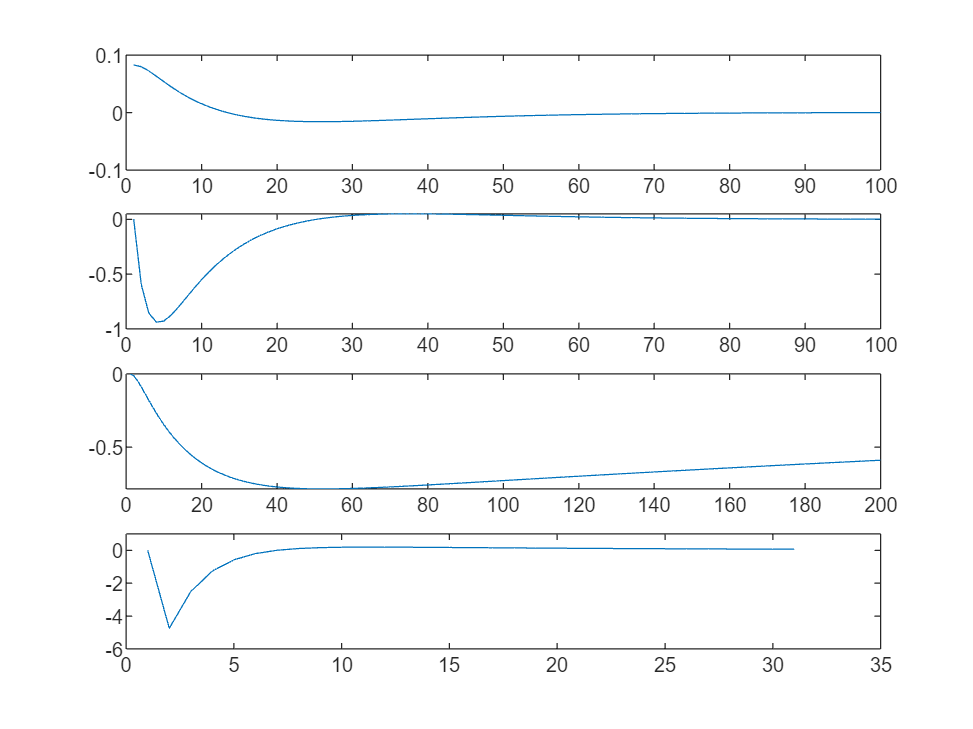


subplot(4,1,1)
plot(X1_k)
ylim([-0.1,0.1])
hold on 
subplot(4,1,2)
plot(X2_k)
hold on 
subplot(4,1,3)
plot(X3_k)
hold on 
subplot(4,1,4)
plot(UK)
ylim([-6,1])